clc
clear all
close all
%% %% Trajectory Planning Position
%p are the coordinates of the assigned points. 
%p=[ pe_x  pe_y  pe_z  type  delta  alpha ]
%4th dimension specifies wheater the path is linear = '0'(default), circular = '1' or 
%goal: derive path primitives p_e, path velocities p_e_dot and acceleration p_e_dotdot for internal points of each path
%MERY:I have added a column for concave(1) or convex(0) curve  
global a1  a2  d0  l1  l2 T Tc 
T=12; %second to travel from 2 consecutive points of the path
Tc = 0.001; %sampling time

p = [
        1         0.001       0         0         0    0         0     % 1       istante 0
        1       0       0         0         0    0       0     % 2       istante 3
        1        0.001     0         0         0    0         0
        1         0       0         0         0    0         0     % 3       istante 6
        1      0.001       0         0         0    0       0
        1      0    0         0         0    0         0
        1         0.001       0         0         0    0         0
        1         0.002   0         0         0    0         0
    ];

npoints=length(p(:,1))-1;

tk1 = 0:T:npoints*T; %time istant to pass in the assigned points

%EE s,v,a Trajectory
p_e = zeros(3,npoints*T*1000)';
p_edot = zeros(3,npoints*T*1000)';
p_eddot = zeros(3,npoints*T*1000)';

s =zeros(1,npoints*T*1000)';
sdot = zeros(1,npoints*T*1000)';
si=0;
for i=1:npoints
    if p(i,4)==0
    %Algoritm for linear path
    [p_e((i-1)*12000+1:i*12000,:), p_edot((i-1)*12000+1:i*12000,:), p_eddot((i-1)*12000+1:i*12000,:),s((i-1)*12000+1:i*12000,1), sdot((i-1)*12000+1:i*12000,1),sf] = linearpath(p(i,:),p(i+1,:),tk1(i),tk1(i+1),si);
    si=sf;
    
        elseif p(i,4)== 1
        %Algoritm for ciruclar path
        [p_e((i-1)*12000+1:i*12000,:), p_edot((i-1)*12000+1:i*12000,:), p_eddot((i-1)*12000+1:i*12000,:),s((i-1)*12000+1:i*12000,1), sdot((i-1)*12000+1:i*12000,1),sf] = circularpath(p(i,:),p(i+1,:),tk1(i),tk1(i+1),si);
        si=sf;
            
    end  
    % %Gabriele
    % p_finale=zeros(15001,3);
    % p_finale(:,1)=0.5;
    % p_finale(:,2)=0.6;
    % p_finale(:,3)=0.25;
    % p_e(57000:72000,:)=p_finale;
    % p_edot(57000:72000,:)=zeros(15001,3);
    % p_eddot(57000:72000,:)=zeros(15001,3);

    
end



%Plot
figure('Name','Traiettoria End Effector')
% plot3(p(1:4,1),p(1:4,2),p(1:4,3),'o','MarkerFaceColor','r','MarkerSize',5);
% hold on
%plot3(p(17:end,1),p(17:end,2),p(17:end,3),'o','MarkerFaceColor','b','MarkerSize',5);
% brown = [0.65, 0.16, 0.16];
% hold on
plot3(p_e(1:84000,1),p_e(1:84000,2),p_e(1:84000,3),'LineWidth',1.5);
hold on
% azzurro_napoli = [0 0.62 0.91];
%plot3(p_e(45001:end,1),p_e(45001:end,2),p_e(45001:end,3),'Color',azzurro_napoli,'LineWidth',1.5);
legend('Punti di Passaggio (V)','Punti di Passaggio (N)','Traiettoria End Effector(V)','Traiettoria End Effector(N)','Interpreter', 'latex')

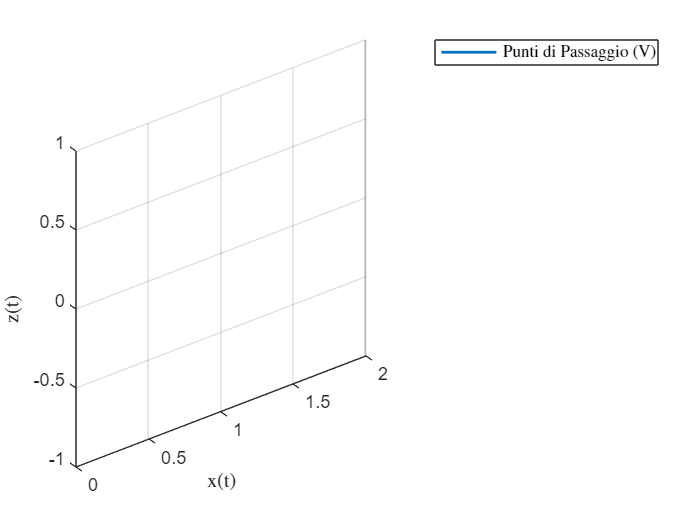

axis equal
% axis ([0.1,0.8,0.4,0.7,-0.1,0.5])
xlabel('x(t)','Interpreter', 'latex')
ylabel('y(t)','Interpreter', 'latex')
zlabel('z(t)','Interpreter', 'latex')
grid on
hold off

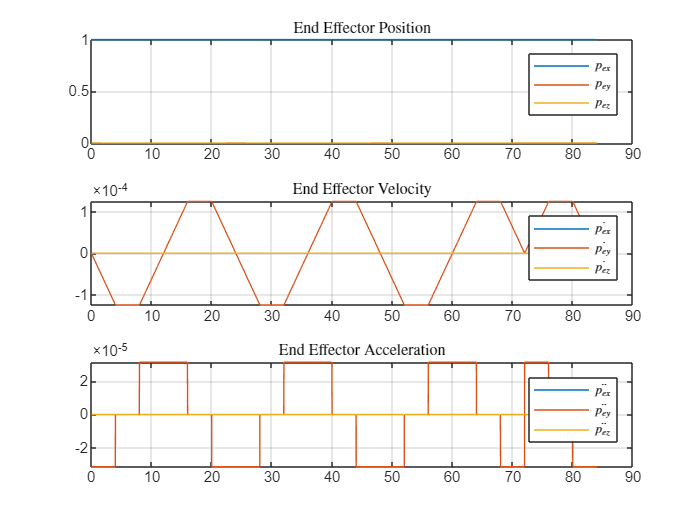



%Position, Velocity and acceleration of EE
figure ('Name','Position, Velocity and Acceleration of E.E.')
tiledlayout(3,1);

nexttile
plot(0:Tc:84-Tc,[p_e(:,1), p_e(:,2), p_e(:,3)]);
legend('$p_{ex}$','$p_{ey}$','$p_{ez}$', 'Interpreter','latex')
title('End Effector Position', 'Interpreter','latex');
grid on

nexttile
plot(0:Tc:84-Tc,[p_edot(:,1), p_edot(:,2), p_edot(:,3)]);
legend('$\dot{p_{ex}}$','$\dot{p_{ey}}$','$\dot{p_{ez}}$', 'Interpreter','latex')
title("End Effector Velocity", 'Interpreter','latex');
grid on

nexttile
plot(0:Tc:84-Tc,[p_eddot(:,1), p_eddot(:,2), p_eddot(:,3)]);
legend('$\ddot{p_{ex}}$','$\ddot{p_{ey}}$','$\ddot{p_{ez}}$', 'Interpreter','latex')
title('End Effector Acceleration', 'Interpreter','latex');
grid on

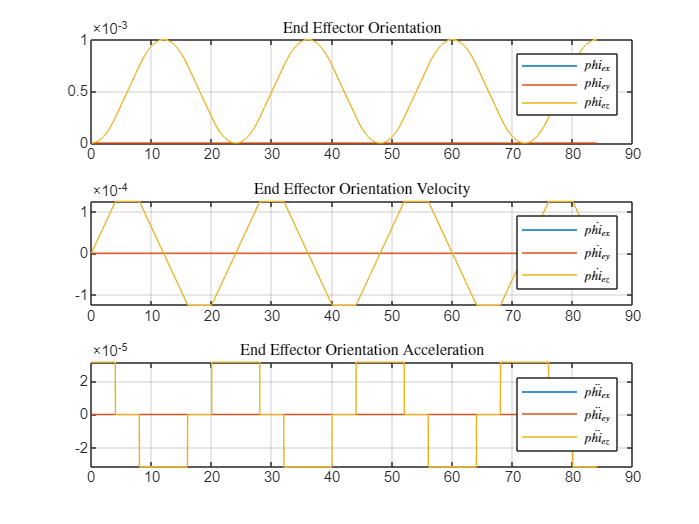



%% ORIENTAMENTO
phi = [0 0 0
       0 0 0.001
       0 0 0
       0 0 0.001
       0 0 0
       0 0 0.001
       0 0 0
       0 0 0.001];

norient=length(phi(:,1))-1;

tk2 = 0:npoints*T/norient:npoints*T;
nvalue=length(s)/ norient;

s_or =zeros(1,npoints*T*1000)';
s_ordot = zeros(1,npoints*T*1000)';
si=0;
thetai=0;
for i=1:norient
    %Algoritm for linear path
    R_i=[cos(phi(i,3)) -sin(phi(i,3)) 0 
        sin(phi(i,3)) cos(phi(i,3)) 0
        0 0 1];

    R_f=[cos(phi(i+1,3)) -sin(phi(i+1,3)) 0 
        sin(phi(i+1,3)) cos(phi(i+1,3)) 0
        0 0 1];

    R_if=R_i'*R_f;

    thetaf=acos((R_if(1,1)+R_if(2,2)+R_if(3,3)-1)/2);

    r=0.5/sin(thetaf)*[R_if(3,2)-R_if(2,3)
        R_if(1,3)-R_if(3,1)
        R_if(2,1)-R_if(1,2)];
    
%%%%%%%%%%%%%%
    % [phi_e((i-1)*nvalue+1:i*nvalue,:), phi_edot((i-1)*nvalue+1:i*nvalue,:), phi_eddot((i-1)*nvalue+1:i*nvalue,:),s_or((i-1)*nvalue+1:i*nvalue,1), s_ordot((i-1)*nvalue+1:i*nvalue,1),sf] = linearpath(0,thetaf,tk2(i),tk2(i+1),si);
%%%%%%%%%%%%%%%%

    sf = si + norm(thetaf-thetai); %lunghezza tratto da percorrere

    dt = 0:Tc:T;

    s = zeros(1,length(dt)-1);
    sdot = zeros(1,length(dt)-1);
    sdotdot = zeros(1,length(dt)-1);

    sdot_c=1.5*abs(sf-si)/T; %scelta della velocità di crociera

%Il profilo è simmetrico rispetto sm = (si+sf)/2 e tm = tf/2 ->sdotdot è
%uguale sia in acc che in dece
%impongo la continuità  della velocità nel punto in cui cambio andamento
%(tc) + che la velcità raggiunta in quel punto sia pari a sdot_c
%ho 2 eq in 2 incognite: sdotdot_c e tc

    tc = (sdot_c*T -(sf-si))/sdot_c;
    sdotdot_c = sdot_c/tc;

%eq del moto
for it = 1:length(dt)-1
    if(dt(it)<tc) %TRATTO IN ACCELERAZIONE
        s(it) = si + 1/2*sdotdot_c*dt(it)^2;
        sdot(it) = sdotdot_c*dt(it);
        sdotdot(it) = sdotdot_c;
        elseif(dt(it)>=tc && dt(it)<T-tc) %TRATTO A VEL COSTANTE
            s(it) = si - 1/2*sdotdot_c*tc^2 + sdot_c*dt(it);
           % sdot(i) = sdotdot_c;
           sdot(it) = sdot_c;
            sdotdot(it) = 0;
            elseif(dt(it)>=T-tc) %TRATTO IN DECELERAZIONE
              s(it) = sf - 1/2*sdotdot_c*(dt(end)-dt(it))^2;
              sdot(it) = sdot_c+sdotdot_c*((T-tc)-dt(it));
              sdotdot(it) = -sdotdot_c;  
    end
end
theta_t = thetai+(s-si)'*(thetaf-thetai)/(sf-si);

theta_t=theta_t';


theta_t_dot = sdot'*(thetaf-thetai)/(sf-si);
theta_t_dot_dot = sdotdot'*(thetaf-thetai)/(sf-si); 
sf=s(end);

for ig=1:12000
    omega(:,ig)=theta_t_dot(ig)*r;
    omega_dot(:,ig)=theta_t_dot_dot(ig)*r;
end

omega_new(:,(i-1)*nvalue+1:i*nvalue)=omega;
omega_dot_new(:,(i-1)*nvalue+1:i*nvalue)=omega_dot;


R=[r(1)^2*(1-cos(theta_t))+cos(theta_t); r(1)*r(2)*(1-cos(theta_t))-r(3)*sin(theta_t); r(1)*r(3)*(1-cos(theta_t))+r(2)*sin(theta_t)
   r(1)*r(2)*(1-cos(theta_t))+r(3)*sin(theta_t); r(2)^2*(1-cos(theta_t))+cos(theta_t); r(2)*r(3)*(1-cos(theta_t))-r(1)*sin(theta_t)
   r(1)*r(3)*(1-cos(theta_t))-r(2)*sin(theta_t); r(2)*r(3)*(1-cos(theta_t))+r(1)*sin(theta_t); r(3)^2*(1-cos(theta_t))+cos(theta_t)];

R_t(:,(i-1)*nvalue+1:i*nvalue)=R;

    
si=sf;
% thetai=thetaf;


Ri_new(:,(i))=[R_i(1,1);R_i(1,2);R_i(1,3);
    R_i(2,1);R_i(2,2);R_i(2,3);
    R_i(3,1);R_i(3,2);R_i(3,3)];


end


for i=1:84000

    R_new=[R_t(1,i) R_t(2,i) R_t(3,i)
        R_t(4,i) R_t(5,i) R_t(6,i)
        R_t(7,i) R_t(8,i) R_t(9,i)];

     if i >= 1 && i <= 12000
        g = 1;
    elseif i >= 12001 && i <= 24000
        g = 2;
    elseif i >= 24001 && i <= 36000
        g = 3;
    elseif i >= 36001 && i <= 48000
        g = 4;
    elseif i >= 48001 && i <= 60000
        g = 5;
    elseif i >= 60001 && i <= 72000
        g = 6;
    elseif i >= 72001 && i <= 84000
        g = 7;
    end

    Ri=[Ri_new(1,g) Ri_new(2,g) Ri_new(3,g)
    Ri_new(4,g) Ri_new(5,g) Ri_new(6,g)
    Ri_new(7,g) Ri_new(8,g) Ri_new(9,g)];

    R_new=Ri*R_new;

    psi_new(i)=atan2(R_new(2,1),R_new(1,1));
    

    theta_new(i)=atan2(-R_new(3,1),sqrt(R_new(3,2)^2+R_new(3,3)^2));

    phi_new(i)=atan2(R_new(3,2),R_new(3,3));

    omega_e(:,i)=R_i*omega_new(:,i);
    omega_e_dot(:,i)=R_i*omega_dot_new(:,i);


end

omega_e=omega_e';
omega_e_dot=omega_e_dot';

phi_new=phi_new';

theta_new=theta_new';
psi_new=psi_new';

phi_e=[phi_new theta_new psi_new];

t = (0:Tc:84-Tc)';

figure ('Name','Position, Velocity and acceleration of Orientation E.E.')
tiledlayout(3,1);

nexttile
plot(0:Tc:84-Tc,[phi_e(:,1), phi_e(:,2), phi_e(:,3)]);
legend('$phi_{ex}$','$phi_{ey}$','$phi_{ez}$', 'Interpreter','latex')
title('End Effector Orientation', 'Interpreter','latex');
grid on

nexttile
 plot(0:Tc:84-Tc,[omega_e(:,1), omega_e(:,2), omega_e(:,3)]);
 legend('$\dot{phi_{ex}}$','$\dot{phi_{ey}}$','$\dot{phi_{ez}}$', 'Interpreter','latex')
 title("End Effector Orientation Velocity", 'Interpreter','latex');
grid on

nexttile
plot(0:Tc:84-Tc,[omega_e_dot(:,1), omega_e_dot(:,2), omega_e_dot(:,3)]);
legend('$\ddot{phi_{ex}}$','$\ddot{phi_{ey}}$','$\ddot{phi_{ez}}$', 'Interpreter','latex')
title('End Effector Orientation Acceleration', 'Interpreter','latex');
grid on


xd = timeseries([p_e , phi_e],t);
xd_dot = timeseries([p_edot , omega_e],t);
xd_ddot = timeseries([p_eddot , omega_e_dot],t);


